## Minimum time

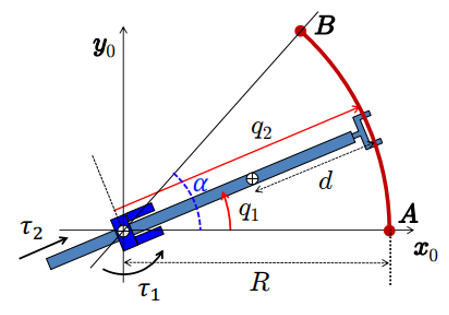

syms q1 q2 dq1 dq2 m1 L I1 I2 d1 g0 positive

% Joint 1
x1 = d1*cos(q1);
y1 = d1*sin(q1);

vx1 = diff(x1,q1)*dq1+diff(x1,q2)*dq2;
vy1 = diff(y1,q1)*dq1+diff(y1,q2)*dq2;

T1_tr = 0; % il link 1 non trasla !!
T1_rot = 0.5*I1*dq1^2;

T1 = T1_rot;

% Joint 2
x2 = (q2-d1)*cos(q1);
y2 = (q2-d1)*sin(q1);

vx2 = diff(x2,q1)*dq1+diff(x2,q2)*dq2;
vy2 = diff(y2,q1)*dq1+diff(y2,q2)*dq2;

T2_tr = 0.5*m2*dq2^2    

$$T2\_tr = \frac{{{\mathrm{dq}}_{2}}^{2}}{2}$$

T2_rot = 0.5*(I2 + m2*(q2-d1)^2)*(dq1^2);

T2 = T2_rot;

T = T1+T2

$$T = \frac{I_{1}\,{{\mathrm{dq}}_{1}}^{2}}{2}+{{\mathrm{dq}}_{1}}^{2}\,\left(\frac{I_{2}}{2}+\frac{{\left(d_{1}-q_{2}\right)}^{2}}{2}\right)$$


% Inertia Matrix
M11 = diff(diff(T, dq1), dq1);
M12 = diff(diff(T, dq1), dq2);

M21 = diff(diff(T, dq2), dq1);
M22 = diff(diff(T, dq2), dq2);

M = [M11, M12;
     M21, M22;];

%M = simplify(M);

disp('The inertia matrix M(q) is:');

The inertia matrix M(q) is:


disp(M);

$$\left(\begin{array}{cc} I_{1}+I_{2}+{\left(d_{1}-q_{2}\right)}^{2} & 0\\ 0 & 0 \end{array}\right)$$


% Potential Energy and Gravity Terms
U1 = m1*g0*(d1*sin(q1));
U2 = m2*g0*(q2*sin(q1));
U = [U1+U2;];
g_q = simplify([diff(U,q1); diff(U,q2);], Steps=100)

$$g\_q = \left(\begin{array}{c} g_{0}\,\cos\left(q_{1}\right)\,\left(q_{2}+d_{1}\,m_{1}\right)\\ g_{0}\,\sin\left(q_{1}\right) \end{array}\right)$$


% using the Christoffel symbols for a 3-DOF system
q  = [q1; q2;];
dq = [dq1; dq2;];

% Inizializza la matrice C(q, dq) (3x3) a zeri simbolici:
C = sym(zeros(2,2));

% Formula dei coefficienti di Christoffel (Robotics):
%   C(i,j) = 1/2 * SUM_k [ dM(i,j)/dq_k + dM(i,k)/dq_j - dM(k,j)/dq_i ] * dq_k
% Poi il vettore c(q,dq) = C(q,dq) * dq
for i = 1:2
    for j = 1:2
        % Costruisco ogni elemento C(i,j):
        tmp = 0;
        for k = 1:2
            tmp = tmp + 0.5 * ( ...
                diff(M(i,j), q(k)) + ...
                diff(M(i,k), q(j)) - ...
                diff(M(k,j), q(i)) ) * dq(k);
        end
        C(i,j) = simplify(tmp);  % semplifico
    end
end

% Finalmente calcolo il vettore c(q, dq):
c_vec = C * dq;

disp('La matrice di Coriolis C(q,dq) è:');

La matrice di Coriolis C(q,dq) è:


disp(C);

$$\left(\begin{array}{cc} -{\mathrm{dq}}_{2}\,\left(d_{1}-q_{2}\right) & -{\mathrm{dq}}_{1}\,\left(d_{1}-q_{2}\right)\\ {\mathrm{dq}}_{1}\,\left(d_{1}-q_{2}\right) & 0 \end{array}\right)$$


disp('Il vettore c(q,dq) = C(q,dq)*dq è:');

Il vettore c(q,dq) = C(q,dq)*dq è:


disp(c_vec);

$$\left(\begin{array}{c} -2\,{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{2}\,\left(d_{1}-q_{2}\right)\\ {{\mathrm{dq}}_{1}}^{2}\,\left(d_{1}-q_{2}\right) \end{array}\right)$$


disp('La matrice di Coriolis C(q,dq) è:');

La matrice di Coriolis C(q,dq) è:


disp(C);

$$\left(\begin{array}{cc} -{\mathrm{dq}}_{2}\,\left(d_{1}-q_{2}\right) & -{\mathrm{dq}}_{1}\,\left(d_{1}-q_{2}\right)\\ {\mathrm{dq}}_{1}\,\left(d_{1}-q_{2}\right) & 0 \end{array}\right)$$


disp('Il vettore c(q,dq) = C(q,dq)*dq è:');

Il vettore c(q,dq) = C(q,dq)*dq è:


disp(c_vec);

$$\left(\begin{array}{c} -2\,{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{2}\,\left(d_{1}-q_{2}\right)\\ {{\mathrm{dq}}_{1}}^{2}\,\left(d_{1}-q_{2}\right) \end{array}\right)$$

### Plot